# **Miniproject #1**

## Author : Mrinmoy Sarkar

## Date : 12/5/2017

## Email : msarkar@aggies.ncat.edu

## Bannar Id: 950-363-260

# **{a}**

# **# Parameters for the Selected System**

%% parameters
M = 30

M = 30

mw = 2

mw = 2

r = 0.1

r = 0.1000

d = 0.7

d = 0.7000

K_tL = 0.5

K_tL = 0.5000

K_tR = 0.5

K_tR = 0.5000

B_L = 0.1

B_L = 0.1000

B_R = 0.1

B_R = 0.1000

J_m = 0.0263

J_m = 0.0263

J_M = 2.45

J_M = 2.4500


alpha = M*r^2 + 3*mw*r^2 + 3*J_m + J_M*(r^2/d^2)/2 - ...
    2*J_M^2*(r^2/d^2)/(M*r^2) + 3*mw*r^2 + 3*J_m + J_M*(r^2/d^2)

alpha = -0.1639


beta = 2*J_M^2*(r^4/d^4)/(M*r^2) + 3*mw*r^2 + 3*J_m + J_M*(r^2/d^2)

beta = 0.2056


gama = 2*J_M*(r^2/d^2)/(M*r^2) + 3*mw*r^2 + 3*J_m + J_M*(r^2/d^2)

gama = 0.5222

# **# State-Space Representation of the System**

%% system matrix
A = [0     1        0        0     0          0;...
     0 -B_L/alpha -1/alpha   0 beta/alpha gama/alpha;...
     0     0        0        0     0          0;...
     0     0        0        0    1/alpha     0;...
     0 beta/alpha gama/alpha 0 -B_R/alpha -1/alpha;...
     0     0        0        0     0          0]

A =          0    1.0000         0         0         0         0
         0    0.6103    6.1025         0   -1.2545   -3.1869
         0         0         0         0         0         0
         0         0         0         0   -6.1025         0
         0   -1.2545   -3.1869         0    0.6103    6.1025
         0         0         0         0         0         0


 
 B = [    0                 0;...
      K_tL/alpha 2*K_tL*gama/alpha;...
          0                 0;...
          0                 0;...
      2*K_tR*gama/alpha K_tR/alpha;...
          0                 0]

B =          0         0
   -3.0513   -3.1869
         0         0
         0         0
   -3.1869   -3.0513
         0         0


   
 C = [1 1 0 1 1 0]

C =      1     1     0     1     1     0


 D = [0 0]

D =      0     0



$$$\dot{\mathbf{x}} = A\mathbf{x} + BU\\
y = C\mathbf{x} + DU$$$


                  where,

                             $$A = \pmatrix{0 & 1 & 0 & 0 & 0 & 0 \cr
0 & 0.6103 & 6.1025 & 0 & -1.2545 & -3.1869 \cr 
0 & 0 & 0 & 0 & 0 & 0 \cr
0 & 0 & 0 & 0 & -6.1025 & 0 \cr 
0 & -1.2545 & -3.1869 & 0 & 0.6103 & 6.1025 \cr
0 & 0 & 0 & 0 & 0 & 0 
}$$ , $$B = \pmatrix{
         0      &   0 \cr
   -3.0513  & -3.1869 \cr
         0        & 0 \cr
         0       &  0 \cr
   -3.1869  & -3.0513 \cr
         0      &   0 

}
$$

$$C=\pmatrix{1 &1 &0 &1 &1 &0}
$$ , $$
D=\pmatrix{0&0}
$$

# **# Check the Controllability of the System**

**Step1: find the C matrix;**

**Where,** $$
C=\pmatrix{B&AB&A^2B&A^3B&A^4B&A^5B}
$$

Ct = ctrb(A,B)

Ct =          0         0   -3.0513   -3.1869    2.1359    1.8829   -1.0586   -1.5304    1.2738    0.3941    0.2830   -1.3575
   -3.0513   -3.1869    2.1359    1.8829   -1.0586   -1.5304    1.2738    0.3941    0.2830   -1.3575    1.8756   -1.1834
         0         0         0         0         0         0         0         0         0         0         0         0
         0         0   19.4484   18.6204  -11.4904  -13.0344    9.3393    6.4602   -2.4048   -7.7735    8.2841   -1.7270
   -3.1869   -3.0513    1.8829    2.1359   -1.5304   -1.0586    0.3941    1.2738   -1.3575    0.2830   -1.1834    1.8756
         0         0         0         0         0         0         0         0         0         0         0         0



$$$
C = \pmatrix{ 0        &  0 &  -3.0513&   -3.1869&    2.1359 &   1.8829&   -1.0586&   -1.5304&    1.2738 &   0.3941 &   0.2830 &  -1.3575\cr
   -3.0513  & -3.1869 &   2.1359&    1.8829&   -1.0586&   -1.5304&    1.2738&    0.3941&    0.2830&   -1.3575&    1.8756&   -1.1834\cr
         0   &      0 &        0 &        0  &       0&         0    &     0  &       0  &       0    &     0    &     0   &      0\cr
         0   &      0  & 19.4484 &  18.6204&  -11.4904 & -13.0344  &  9.3393  &  6.4602  & -2.4048  & -7.7735   & 8.2841 &  -1.7270\cr
   -3.1869 &  -3.0513 &   1.8829 &   2.1359 &  -1.5304 &  -1.0586 &   0.3941   & 1.2738 &  -1.3575  &  0.2830 &  -1.1834  &  1.8756\cr
         0     &    0    &     0   &      0  &       0&         0      &   0    &     0   &      0       &  0     &    0   &      0
}
$$$


**Step2: find the rank of C matrix and check if C is full row rank or not**

rnk = rank(Ct)

rnk = 4

controllable = rank(Ct) == size(Ct,1)

controllable = logical
   0


## **So, **$$
\rho(C) \neq r
$$** and thats why the system is not controllable.**

# **# Check if the system is Stable or not**

[num,den] = ss2tf(A,B,C,D,2)

num =          0   -6.2382   27.0660  -29.9881   -0.0000         0         0


den =     1.0000   -1.2205   -1.2013         0         0         0         0


sys = tf(num,den)


sys =
 
                            
  -6.238 s^5 + 27.07 s^4    
                            
          - 29.99 s^3       
                            
             - 8.792e-15 s^2
                            
  --------------------------
                            
  s^6 - 1.221 s^5           
                            
                 - 1.201 s^4
                            
 
Continuous-time transfer function.




stability = isstable(sys)

stability = logical
   0


pl = pole(sys)

pl =          0
         0
         0
         0
    1.8647
   -0.6442


## **Remark: The System is not stable**

# **# Check the observability of the System**

**Step1: Check if **$(A , C)$ **is observable or not**

**find the O matrix. where, **$O=\pmatrix{C \cr CA \cr CA^2 \cr CA^3\cr CA^4 \cr CA^5}$

O = obsv(A,C)

O =     1.0000    1.0000         0    1.0000    1.0000         0
         0    0.3558    2.9156         0   -6.7467    2.9156
         0    8.6807   23.6726         0   -4.5635  -42.3060
         0   11.0223   67.5181         0  -13.6747  -55.5140
         0   23.8809  110.8441         0  -22.1722 -118.5773
         0   42.3878  216.3952         0  -43.4886 -211.4132


**Step2: Check if O is full column rank or not**

rk = rank(O)

rk = 4

observability = rk == size(O,2)

observability = logical
   0


## **Remark: As **$\rho{(O)} \neq c$** the system is not observable**

# **# Decompose the System into Controllable and Uncontrollolable part**

If the controllability matrix of (*A*, *B*) has rank *r* ≤ *n*, where *n* is the size of *A*, then there exists a similarity transformation such that


$$$
\bar{A} = TAT^T, \bar{B}=TB,\bar{C}=CT^T
$$$


where *T* is unitary, and the transformed system has a *staircase* form, in which the uncontrollable modes, if there are any, are in the upper left corner.


$$$
\bar{A}=\pmatrix{A_{\bar{c}}&0\cr A_{21} & A_{c}},\bar{B}=\pmatrix{0\cr B_{c}},\bar{C}=\pmatrix{C_{\bar{c}}&C_{c}}
$$$


where ($$A_{c},B_{c}$$) is controllable, all eigenvalues of $$A_{\bar{c}}$$ are uncontrollable, and $$C_c(sI-A_c)^{-1}B_c=C(sI-A)^{-1}B$$.

`[Abar,Bbar,Cbar,T,k] = ctrbf(A,B,C)` decomposes the state-space system represented by `A`, `B`, and `C` into the controllability staircase form, `Abar`, `Bbar`, and `Cbar`, described above. `T` is the similarity transformation matrix and `k` is a vector of length *n*, where *n* is the order of the system represented by `A`. Each entry of `k` represents the number of controllable states factored out during each step of the transformation matrix calculation. The number of nonzero elements in `k` indicates how many iterations were necessary to calculate `T`, and `sum(k)`is the number of states in $A_c$, the controllable portion of `Abar`.

[Abar,Bbar,Cbar,T,kbar] = ctrbf(A,B,C)

Abar =          0         0         0         0         0         0
    0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000
   -0.0000    0.0000    0.0000    0.0000    0.7071   -0.7071
    0.0000    0.0000   -0.0000    0.0000   -4.3151   -4.3151
   -6.5686    6.5686    0.0000    0.0000    1.8647    0.0000
    2.0616    2.0616    0.0000    0.0000         0   -0.6442


Bbar =          0         0
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0959    0.0959
   -4.4111   -4.4111


Cbar =          0    0.0000   -1.0000    1.0000    0.0000    1.4142


T =          0         0    1.0000         0         0         0
    0.0000    0.0000         0         0   -0.0000    1.0000
   -1.0000   -0.0000         0    0.0000    0.0000    0.0000
    0.0000    0.0000         0    1.0000   -0.0000    0.0000
    0.0000   -0.7071         0         0    0.7071         0
   -0.0000    0.7071         0         0    0.7071         0


kbar =      2     2     0     0     0     0


**Extract the Controllable and Uncontrollable part from Abar, Bbar and Cbar:**

Auc = Abar(1:size(Abar,1)-sum(kbar),1:size(Abar,1)-sum(kbar))

Auc =    1.0e-29 *

         0         0
    0.6537   -0.6860


Buc = Bbar(1:size(Bbar,1)-sum(kbar),1:2)

Buc =    1.0e-30 *

         0         0
    0.4438    0.2482


Cuc = Cbar(1:size(Abar,1)-sum(kbar))

Cuc =    1.0e-15 *

         0    0.9992


Duc = zeros(1,size(Buc,2))

Duc =      0     0


**Now Check if the uncontrollable part is stable or not:**

[num,den] = ss2tf(Auc,Buc,Cuc,Duc,2)

num =    1.0e-45 *

         0    0.2480         0


den =     1.0000    0.0000         0


sys = tf(num,den)


sys =
 
     2.48e-46 s
  ----------------
  s^2 + 6.86e-30 s
 
Continuous-time transfer function.



stability = isstable(sys)

stability = logical
   0


pl = round(pole(sys),4)

pl =      0
     0


**Remark: The uncontrollable part has poles which values are zero, means on imaginary axis. So, the system is marginally stable**

**Extract the Controllable System Matrix:**

Ac = Abar(size(Abar,1)-sum(kbar)+1:end,1+size(Abar,1)-sum(kbar):end) %MSYS.A

Ac =     0.0000    0.0000    0.7071   -0.7071
   -0.0000    0.0000   -4.3151   -4.3151
    0.0000    0.0000    1.8647    0.0000
    0.0000    0.0000         0   -0.6442


Bc = Bbar(size(Bbar,1)-sum(kbar)+1:end,1:2)%MSYS.B

Bc =    -0.0000   -0.0000
    0.0000    0.0000
   -0.0959    0.0959
   -4.4111   -4.4111


Cc = Cbar(1+size(Abar,1)-sum(kbar):end)%MSYS.C

Cc =    -1.0000    1.0000    0.0000    1.4142


Dc = zeros(size(Cc,1),size(Bc,2)) %MSYS.D

Dc =      0     0


# **# Design of State-Feedback Controller for the Controllable Part**

**Step1: Check if **$(A_c , B_c)$ **is controllable or not**

Ct = ctrb(Ac,Bc)

Ct =    -0.0000   -0.0000    3.0513    3.1869   -2.1359   -1.8829    1.0586    1.5304
    0.0000    0.0000   19.4484   18.6204  -11.4904  -13.0344    9.3393    6.4602
   -0.0959    0.0959   -0.1789    0.1789   -0.3336    0.3336   -0.6221    0.6221
   -4.4111   -4.4111    2.8417    2.8417   -1.8307   -1.8307    1.1794    1.1794


controllable = rank(Ct) == size(Ct,1)

controllable = logical
   1


**So, **$(A_c , B_c)$ **is controllable**

**Step2: Check if eigen values of **$A_c$ **are distinct or not**

ev = round(eig(Ac), 4)

ev =     1.8647
   -0.6442
         0
         0


fprintf('%d\n',ev)

1.864700e+00
-6.442000e-01
0
0


iseigdistinct = length(ev) == length(unique(ev))

iseigdistinct = logical
   0


**So, All eigen values of **$A_c
$** are not distinct**

**Step3: Now let,**

K1 = zeros(size(Bc'));
K1(1,1) = 1;
K1(2,3) = 0

K1 =      1     0     0     0
     0     0     0     0


A1 = Ac-Bc*K1

A1 =     0.0000    0.0000    0.7071   -0.7071
   -0.0000    0.0000   -4.3151   -4.3151
    0.0959    0.0000    1.8647    0.0000
    4.4111    0.0000         0   -0.6442


ev = round(eig(A1), 4)

ev =   -0.3330 + 1.7307i
  -0.3330 - 1.7307i
   1.8865 + 0.0000i
   0.0000 + 0.0000i


iseigdistinct = length(ev) == length(unique(ev))

iseigdistinct = logical
   1


**So, All eigen values of **$A_1
$** are distinct**

Ct = ctrb(A1,Bc)

Ct =    -0.0000   -0.0000    3.0513    3.1869   -2.1359   -1.8829   -8.2516   -8.1938
    0.0000    0.0000   19.4484   18.6204  -11.4904  -13.0344  -50.0028  -55.5207
   -0.0959    0.0959   -0.1789    0.1789   -0.0409    0.6394   -0.2811    1.0116
   -4.4111   -4.4111    2.8417    2.8417   11.6286   12.2271  -16.9130  -16.1826


controllable = rank(Ct) == size(Ct,1)

controllable = logical
   1


**Step4: Now randomly select q** 

q = [1 1]'

q =      1
     1


**Step5: let **$B_1 = B_cq$

B1 = Bc*q

B1 =    -0.0000
    0.0000
         0
   -8.8221


**Step6: Check if **$(A1,B1)$** is controllable or not**

Ct = ctrb(A1,B1)

Ct =    -0.0000    6.2382   -4.0188  -16.4454
    0.0000   38.0688  -24.5248 -105.5235
         0   -0.0000    0.5985    0.7305
   -8.8221    5.6834   23.8558  -33.0956


controllable = rank(Ct) == size(Ct,1)

controllable = logical
   1


**So, **$(A_1 , B_1)$ **is controllable**

**Step7: Now find **$K^T$ **by using Ackermann’s Formula**

**First, define the desired poles using  ITAE prototype**

poles = [-0.424+1.263i -0.424-1.263i -0.6260+0.4141i -0.6260-0.4141i]

poles =   -0.4240 + 1.2630i  -0.4240 - 1.2630i  -0.6260 + 0.4141i  -0.6260 - 0.4141i


**Now, find the Characteristic polynomial **$\Delta_d(\lambda)$**using these poles**

del_d_lambda = poly(poles)

del_d_lambda =     1.0000    2.1000    3.4000    2.7000    0.9999


**So, **$\Delta_d(\lambda) = \lambda^4+2.1\lambda^3+3.4\lambda^2+2.7\lambda+0.9999$

**Now, find **$\Delta_d(A_1)$

del_d_A1 = zeros(size(A1));
for i=1:length(del_d_lambda)-1
    del_d_A1 = del_d_A1 + del_d_lambda(i)*A1^(length(del_d_lambda)-i);
end
del_d_A1 = del_d_A1 + del_d_lambda(end)*eye(size(A1))

del_d_A1 =     3.3626    0.0000    9.0967    0.8431
    8.0083    0.9999 -144.8965    7.0889
    1.2342    0.0000   44.8272   -0.3801
   -5.2592    0.0000   17.4755    3.7506


**Now, find **$K^T$** using Ackermann’s Formula**

K_T = [zeros(1,size(A1,2)-1) 1]*pinv(Ct)*del_d_A1

K_T =     2.4224   -0.1936   38.8003   -0.3764


**Step8: Now find Feedback gain K**

K = K1 + q*K_T

K =     3.4224   -0.1936   38.8003   -0.3764
    2.4224   -0.1936   38.8003   -0.3764


**Step9: Find the FeedForword gain F using the formula given below:**

For asymptotic tracking, $C(-A+BK^T)^{-1}BF = 1$

where, $F=\pmatrix{F_1\cr F_2}$


coeff = Cc*pinv(-Ac+Bc*K)*Bc

coeff =    11.5132  -16.6787


**So, **$-29.3707F_1+90.8695F_2 = 1$

let, $F_1 = 1$

F1 = 1

F1 = 1

F2 = (1-coeff(1))/coeff(2)

F2 = 0.6303

F=[F1;F2]

F =     1.0000
    0.6303


**So, the Controller input is : **$u(t)=-K^Tx(t)+Fr(t)$

**where, **$K^T=\pmatrix{3.4224   &-0.1936   &38.8003  & -0.3764\cr
    2.4224   &-0.1936   &38.8003  & -0.3764}$ **and **$F=\pmatrix{1\cr0.6303}$

# **{b}**

# **# State space  representation of the closed loop system**

AcL = Ac-Bc*K

AcL =     0.0000   -0.0000    0.7071   -0.7071
   -0.0000    0.0000   -4.3151   -4.3151
    0.0959    0.0000    1.8647    0.0000
   25.7821   -1.7079  342.3021   -3.9647


BcL = Bc*F

BcL =    -0.0000
    0.0000
   -0.0355
   -7.1915


CcL = Cc

CcL =    -1.0000    1.0000    0.0000    1.4142


DcL = [0]

DcL = 0

**State Space Representation of Closed-loop System:**


$$$\dot{\mathbf{x}} = \pmatrix{       0   &      0   & 0.7071 &  -0.7071\cr
         0  &       0  & -4.3151 &  -4.3151\cr
    0.0959    &     0    &1.8647    &     0\cr
   25.7821 &  -1.7079  &342.3021 &  -3.9647}\mathbf{x} + \pmatrix{0
\cr         0\cr
   -0.0355\cr
   -7.1915}r\\
y = \pmatrix{-1    &1&0    &1.4142}\mathbf{x} $$$


**Plot the step response of the closed loop system:**

sys = tf(ss(AcL,BcL,CcL,DcL))


sys =
 
                            
  -10.17 s^3 + 27.92 s^2    
                            
          - 4.471 s + 0.9999
                            
  --------------------------
                            
  s^4 + 2.1 s^3 + 3.4 s^2   
                            
            + 2.7 s + 0.9999
                            
 
Continuous-time transfer function.



**Define the time vector:**

dt = 0.01;
tFinal = 30;
t = 0:dt:tFinal;
n = length(t);

**Define the reference signal:**

r = ones(1,n);

**Plot the system response:**

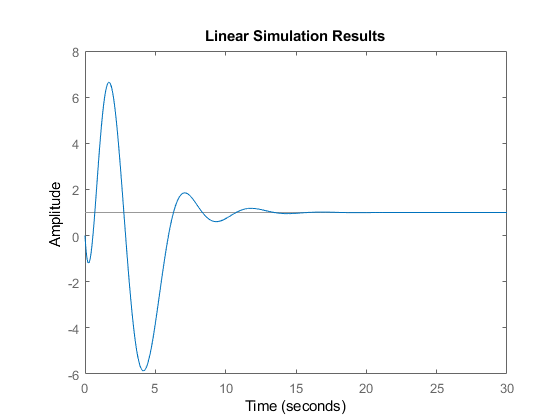

y_Ff = lsim(sys,r,t);
lsim(sys,r,t)

## **Remark:**$y(t)$** asymptotically tracks the reference signal**

# **{c}**

# **# Simulation of the system by adding disturbance**

**Adding disturbance after 10 second:**

n1 = find(t==10);

**Define the distubance:**

w = [zeros(1,n1) ones(1,n-n1)]';
w =[w w];

**Define the u matrix:**

u = [w r'];

**Define new B matrix:**

Bd = [Bc Bc*F]

Bd =    -0.0000   -0.0000   -0.0000
    0.0000    0.0000    0.0000
   -0.0959    0.0959   -0.0355
   -4.4111   -4.4111   -7.1915


Dd = [0 0 0];
sys = tf(ss(AcL,Bd,CcL,Dd))


sys =
 
  From input 1 to output:
                            
  -6.238 s^3 - 18.41 s^2    
                            
           + 87.67 s + 11.51
                            
  --------------------------
                            
  s^4 + 2.1 s^3 + 3.4 s^2   
                            
            + 2.7 s + 0.9999
                            
 
  From input 2 to output:
                            
  -6.238 s^3 + 73.51 s^2    
                            
           - 146.2 s - 16.68
                            
  --------------------------
                            
  s^4 + 2.1 s^3 + 3.4 s^2   
                            
            + 2.7 s + 0.9999
                            
 
  From input 3 to output:
                            
  -10.17 s^3 + 27.92 s^2    
                            
          - 4.471 s + 0.9999
                            
  --------------------------
                            
  s^4 + 2.1 s^3 + 3.4 s^2   
                            
          

**Plot the step responce in the presence of disturbance:**

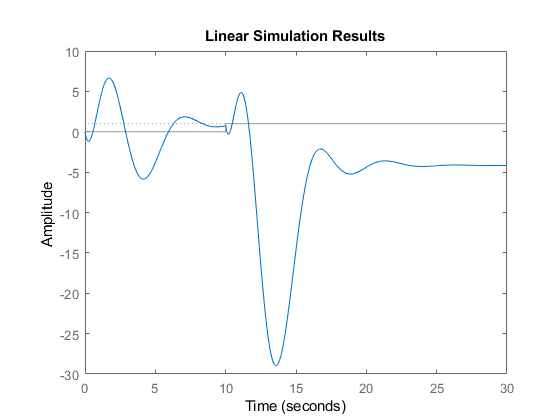

y_Ff_w = lsim(sys,u,t);
lsim(sys,u,t)

## **Remark:**$y(t)$** does not asymptotically tracks the reference signal**

# **{d}**

# **# Design of an Integral Controller**

**Add a new pole for the integral controller:**


poles = [-0.975 -0.424+1.263i -0.424-1.263i -0.6260+0.4141i -0.6260-0.4141i]

poles =   -0.9750 + 0.0000i  -0.4240 + 1.2630i  -0.4240 - 1.2630i  -0.6260 + 0.4141i  -0.6260 - 0.4141i


**Calculate new State Space matrix:**


$$\dot\bar{X} =\pmatrix{A_c&0\cr-C_c &0}\bar{X}+\pmatrix{B_c\cr 0}u+\pmatrix{B_c\cr0}w+\pmatrix{0\cr1}r\\
y=\pmatrix{C_c&0}\bar{X}\\
u=-\pmatrix{K^T &-K_I}\bar{X}$$


Ai = zeros(size(Ac,1)+1);
Ai(1:size(Ac,1),1:size(Ac,2)) = Ac;
Ai(size(Ac,1)+1,1:length(Cc)) = -Cc;
Bi = zeros(size(Bc,1)+1,2);
Bi(1:size(Bc,1),1:size(Bc,2)) = Bc;
Ci = zeros(1,size(Cc,2)+1);
Ci(1,1:length(Cc)) = Cc

Ci =    -1.0000    1.0000    0.0000    1.4142         0


Di = zeros(size(Ci,1),size(Bi,2));
k = place(Ai,Bi,poles)

k =    -3.7621    2.5288  -18.5399    0.6886   -2.0719
    3.8663   -2.5277   18.5363   -0.8560    2.0957


**Calculate the new Closed loop Syatem when W=0:**

K_T = k(1:2,1:size(Ac,2))

K_T =    -3.7621    2.5288  -18.5399    0.6886
    3.8663   -2.5277   18.5363   -0.8560


K_I = -k(:,end)

K_I =     2.0719
   -2.0957


Aicl=Ai

Aicl =     0.0000    0.0000    0.7071   -0.7071         0
   -0.0000    0.0000   -4.3151   -4.3151         0
    0.0000    0.0000    1.8647    0.0000         0
    0.0000    0.0000         0   -0.6442         0
    1.0000   -1.0000   -0.0000   -1.4142         0


Aicl(1:size(Ac,1),1:size(Ac,2)) = Ac - Bc*K_T;
Aicl(1:size(Bc,1),end) = Bc*K_I

Aicl =    -0.0000    0.0000    0.7071   -0.7071   -0.0000
   -0.0000    0.0000   -4.3151   -4.3151    0.0000
   -0.7319    0.4851   -1.6924    0.1482   -0.3998
    0.4594    0.0049   -0.0158   -1.3826    0.1049
    1.0000   -1.0000   -0.0000   -1.4142         0


Bi=[zeros(1,size(Bc,1)) 1]';
Di = zeros(size(Ci,1),size(Bi,2));

**New closed-loop system w=0:**


$$\dot\bar{X} =\pmatrix{A_c-BK^T&BK_I\cr-C_c &0}\bar{X}+\pmatrix{0\cr1}r\\
y=\pmatrix{C_c&0}\bar{X}$$


where, $K^T=\pmatrix{-3.7621 &   2.5288 & -18.5399    &0.6886\cr
    3.8663 &  -2.5277 &  18.5363 &  -0.8560}\\

K_I=\pmatrix{2.0719\cr
   -2.0957}$

syscl = tf(ss(Aicl,Bi,Ci,Di))


syscl =
 
                            
  0.1484 s^3 + 1.89 s^2     
                            
           + 2.25 s + 0.9749
                            
  --------------------------
                            
  s^5 + 3.075 s^4           
                            
          + 5.447 s^3       
                            
          + 6.015 s^2       
                            
          + 3.632 s + 0.9749
                            
 
Continuous-time transfer function.



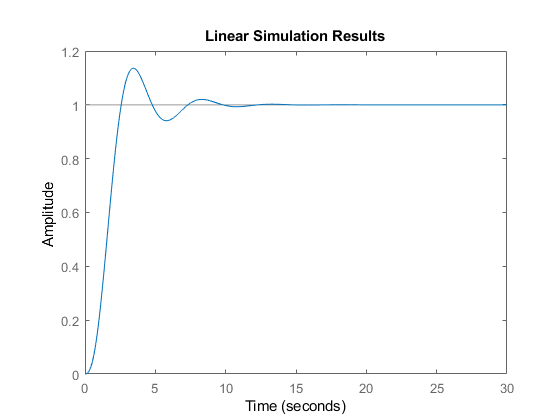

lsim(syscl,r,t);

# **{e}**

# **# Simulation of the Integral controller Closed- loop system by adding disturbance**


Bi=[Bc zeros(size(Bc,1),1);0 0 1]

Bi =    -0.0000   -0.0000         0
    0.0000    0.0000         0
   -0.0959    0.0959         0
   -4.4111   -4.4111         0
         0         0    1.0000


Di = zeros(size(Ci,1),size(Bi,2));

**New Closed-loop system when w = 1 for t>10:**


$$\dot\bar{X} =\pmatrix{A_c-BK^T&BK_I\cr-C_c &0}\bar{X}+\pmatrix{B\cr0}w+\pmatrix{0\cr1}r\\
y=\pmatrix{C_c&0}\bar{X}$$


syscl = tf(ss(Aicl,Bi,Ci,Di))


syscl =
 
  From input 1 to output:
                            
  -6.238 s^4 + 5.842 s^3    
                            
          + 14.55 s^2       
                            
                   + 6.914 s
                            
  --------------------------
                            
  s^5 + 3.075 s^4           
                            
          + 5.447 s^3       
                            
          + 6.015 s^2       
                            
          + 3.632 s + 0.9749
                            
 
  From input 2 to output:
                            
  -6.238 s^4 + 4.874 s^3    
                            
          + 13.31 s^2       
                            
                    + 6.37 s
                            
  --------------------------
                            
  s^5 + 3.075 s^4           
                            
          + 5.447 s^3       
                            
          + 6.015 s^2       
                            
       

**Plot the step responce in the presence of disturbance:**

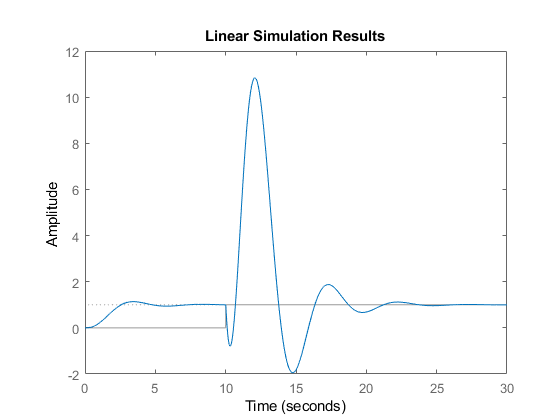

y_I_w = lsim(syscl,u,t);
lsim(syscl,u,t)

## **Remark:**$y(t)$**asymptotically tracks the reference signal**

# **{f}**

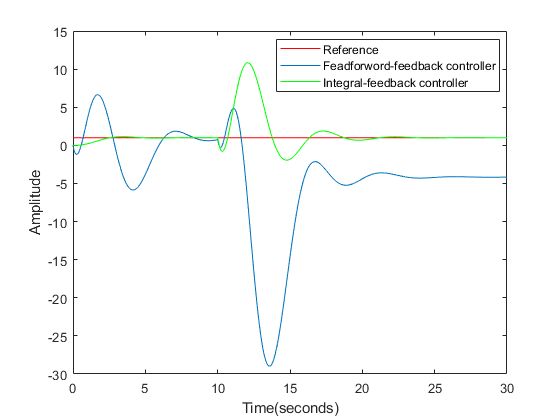

figure
plot(t,ones(size(t)),'r');
hold on;
plot(t,y_Ff_w);
hold on;
plot(t,y_I_w,'g');
xlabel('Time(seconds)')
ylabel('Amplitude')
legend('Reference', 'Feadforword-feedback controller','Integral-feedback controller','Location','best')

figure

## **Remark: The Integral controller can track reference signal asymptotically in the presence of constant disturbance but Feedforward gain controller can not track the reference signal asymptotically.**

# **{g}**

# **# Check the observability of the System**

**Step1: Check if **$(A_c , C_c)$ **is observable or not**

**find the O matrix. where, **$O=\pmatrix{C_c \cr C_cA_c \cr C_cA_c^2 \cr C_cA_c^3}$

O = obsv(Ac,Cc)

O =    -1.0000    1.0000    0.0000    1.4142
   -0.0000    0.0000   -5.0222   -4.5191
   -0.0000   -0.0000   -9.3651    2.9113
   -0.0000   -0.0000  -17.4634   -1.8755


**Step2: Check if O is full column rank or not**

rk = rank(O)

rk = 3

observability = rk == size(O,2)

observability = logical
   0


## **Remark: The system is not observable**

# **# Decompose the System into Observable and UnObservable part**

If the observability matrix of (*A*, C) has rank *r* ≤ *n*, where *n* is the size of *A*, then there exists a similarity transformation such that


$$$
\bar{A} = TAT^T, \bar{B}=TB,\bar{C}=CT^T
$$$


where *T* is unitary, and the transformed system has a *staircase* form, in which the unobsrvable modes, if there are any, are in the upper left corner.


$$$
\bar{A}=\pmatrix{A_{\bar{o}}&0\cr A_{21} & A_{o}},\bar{B}=\pmatrix{B_{\bar{0}}\cr B_{o}},\bar{C}=\pmatrix{0&C_{o}}
$$$


where ($$C_{o}, A_{o}$$) is observable, all eigenvalues of $$A_{\bar{o}}$$ are unobservlable modes.

`[Abar,Bbar,Cbar,T,k] = obsvf(A,B,C)` decomposes the state-space system represented by `A`, `B`, and `C` into the observability staircase form, `Abar`, `Bbar`, and `Cbar`, described above. `T` is the similarity transformation matrix and `k` is a vector of length *n*, where *n* is the order of the system represented by `A`. Each entry of `k` represents the number of observable states factored out during each step of the transformation matrix calculation. The number of nonzero elements in `k` indicates how many iterations were necessary to calculate `T`, and `sum(k)`is the number of states in $A_o$, the controllable portion of `Abar`.

[Abar,Bbar,Cbar,T,kbar] = obsvf(Ac,Bc,Cc)

Abar =    -0.0000    0.7491   -3.5005    2.5111
    0.0000    0.0788   -1.3748    0.8045
   -0.0000    1.1363    2.7395   -0.5119
    0.0000   -0.0000    2.9763   -1.5977


Bbar =     0.0000    0.0000
   -2.5801   -2.6831
    1.7553    1.5934
   -3.1191   -3.1191


Cbar =     0.0000    0.0000   -0.0000    2.0000


T =    -0.7071   -0.7071    0.0000   -0.0000
    0.4218   -0.4218   -0.5368    0.5966
   -0.2684    0.2684   -0.8437   -0.3796
   -0.5000    0.5000    0.0000    0.7071


kbar =      1     1     1     0



Ao = Abar(size(Abar,1)-sum(kbar)+1:end,1+size(Abar,1)-sum(kbar):end)

Ao =     0.0788   -1.3748    0.8045
    1.1363    2.7395   -0.5119
   -0.0000    2.9763   -1.5977


Bo = Bbar(size(Bbar,1)-sum(kbar)+1:end,1:2)

Bo =    -2.5801   -2.6831
    1.7553    1.5934
   -3.1191   -3.1191


Co = Cbar(1+size(Abar,1)-sum(kbar):end)

Co =     0.0000   -0.0000    2.0000


Do = zeros(size(Co,1),size(Bo,2))

Do =      0     0


**Now Define the desired poles:**

**Using ITAE prot****otype:**

multiplier = 5;
poles = [multiplier*-0.7081  multiplier*-0.5210+1.068i multiplier*-0.5210-1.068i]

poles =   -3.5405 + 0.0000i  -2.6050 + 1.0680i  -2.6050 - 1.0680i


**Now, find the Characterist****ic polynomial **$\Delta_d(\lambda)$**using these poles**

del_d_lambda = poly(poles)

del_d_lambda =     1.0000    8.7505   26.3727   28.0643


**So, **$\Delta_d(\lambda) = \lambda^3+8.7505\lambda^2+26.3727\lambda+28.0643$

**Now, find **$\Delta_d(A_o)$

del_d_Ao = zeros(size(Ao));
for i=1:length(del_d_lambda)-1
    del_d_Ao = del_d_Ao + del_d_lambda(i)*Ao^(length(del_d_lambda)-i);
end
del_d_Ao = del_d_Ao + del_d_lambda(end)*eye(size(Ao))

del_d_Ao =    14.7218  -52.6663   17.0151
   63.2650  147.6633  -10.8262
   33.7229  115.9517   -5.7286


**Now, find **$L^T$** using Ackermann’s Formula**

L_T = [zeros(1,size(Ao,2)-1) 1]*pinv(obsv(Ao,Co))*del_d_Ao

L_T =     7.3609  -26.3331    8.5076


L = L_T'

L =     7.3609
  -26.3331
    8.5076


## **So, The designed observer is given below:**


$$\dot{\hat{X}} = (A_o-LC_o)\hat{X}+Bu+Ly\\ \hat{y}=C_o\hat{X}\\where,\\L=\pmatrix{7.3609\cr
  -26.3331\cr
   8.5076}$$


# **{h}**

# **# Put the Controller and Observer together:**

**Calculate the Closed-loop system matrix for the designed controller and observer:**


$$\pmatrix{\dot{X}\cr\dot{\bar{X}}}=\pmatrix{A-BK^T&BK^T\cr0&A-LC}\pmatrix{X\cr\bar{X}}+\pmatrix{BF\cr0}r\\
y=\pmatrix{c &0}\pmatrix{x\cr\bar{x}}$$


Abar(size(Abar,1)-size(Ao,1)+1:end, size(Abar,2)-size(Ao,2)+1:end) = Ao-L*Co;
Aco_cL = zeros(size(Ac,1)+size(Abar,1));
Aco_cL(1:size(Ac,1),1:size(Ac,2)) = Ac-Bc*K;
Aco_cL(size(Ac,1)+1:end,size(Ac,2)+1:end) = T'*Abar*T;
Aco_cL(1:size(Ac,1),size(Ac,2)+1:end) = Bc*K

Aco_cL =     0.0000   -0.0000    0.7071   -0.7071   -0.0000    0.0000   -0.0000    0.0000
   -0.0000    0.0000   -4.3151   -4.3151    0.0000   -0.0000    0.0000   -0.0000
    0.0959    0.0000    1.8647    0.0000   -0.0959         0         0         0
   25.7821   -1.7079  342.3021   -3.9647  -25.7821    1.7079 -342.3021    3.3205
         0         0         0         0    5.9195   -5.9195    0.7071   -9.0785
         0         0         0         0   -5.9195    5.9195   -4.3151    4.0562
         0         0         0         0   18.2658  -18.2658    1.8647  -25.8317
         0         0         0         0   20.4029  -20.4029   -0.0000  -29.4983


Bco_cL = round([Bc*F; zeros(size(Bc,1),1)],4)

Bco_cL =          0
         0
   -0.0355
   -7.1915
         0
         0
         0
         0


Cco_cL = [Cc zeros(1,length(Cc))]

Cco_cL =    -1.0000    1.0000    0.0000    1.4142         0         0         0         0


Dco_cL = [0]

Dco_cL = 0

**So, the a****u****gm****ented Closed-loop  system is given below:**


$$\pmatrix{\dot{X}\cr\dot{\bar{X}}}=\pmatrix{ 0         &0  &  0.7071   &-0.7071&         0         &0         &0  &       0\cr
         0&         0  & -4.3151 &  -4.3151 &        0&         0  &       0&         0\cr
    0.0959   &      0&    1.8647&         0&   -0.0959  &       0  &       0 &        0\cr
   25.7821  & -1.7079 & 342.3021   &-3.9647  &-25.7821 &   1.7079 &-342.3021    &3.3205
         \cr0      &   0  &       0         &0    &5.9195   &-5.9195    &0.7071&   -9.0785
         \cr0        & 0&         0&         0&   -5.9195 &   5.9195&   -4.3151&    4.0562
         \cr0         &0         &0         &0   &18.2658  &-18.2658 &   1.8647  &-25.8317
         \cr0 &        0&         0&         0&   20.4029  &-20.4029         &0  &-29.4983}\pmatrix{X\cr\bar{X}}+



















\pmatrix{   0\cr 0\cr-0.0355\cr
   -7.1915\cr
    0\cr
         0\cr
         0\cr
         0}r\\




y=\pmatrix{-1&    1&  0&  1.4142 &0        &0      &   0  &       0}\pmatrix{x\cr\bar{x}}$$


# **{i}**

# **# Response of the Augmented Closed-loop System**

aug_sys = tf(ss(Aco_cL, Bco_cL, Cco_cL, Dco_cL))


aug_sys =
 
                            
  -10.17 s^3 + 27.91 s^2    
                            
           - 4.429 s + 1.005
                            
  --------------------------
                            
  s^4 + 2.1 s^3 + 3.4 s^2   
                            
            + 2.7 s + 0.9999
                            
 
Continuous-time transfer function.



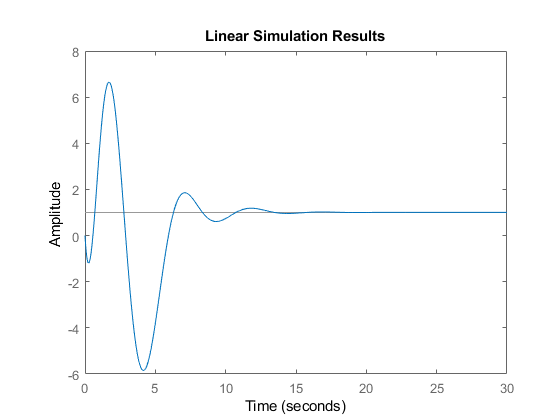


y_aug = lsim(aug_sys,r,t);
lsim(aug_sys,r,t);

## **Remark:**$y(t)$** asymptoti****cally tracks the reference signal**

# **{j}**

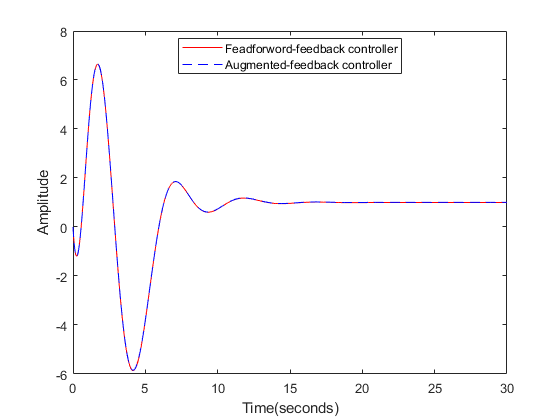

figure
plot(t,y_Ff,'r');
hold on;
plot(t,y_aug,'b--');
xlabel('Time(seconds)')
ylabel('Amplitude')
legend('Feadforword-feedback controller','Augmented-feedback controller','Location','best')

figure

## **Remark****: The Augmented-feedback controller works as good as the Feedforword-feedback controller**

# **############################# END ############################**